LII Model Parameters Based on Lemaire et al.

% Laser-Induced Incandescence (LII) Model
%
% Based on:
% Lemaire, R., Menanteau, S. (2021)
% "Modeling laser-induced incandescence of Diesel soot"
% Applied Physics B, 127:138
% https://doi.org/10.1007/s00340-021-07665-y
%
% This implementation reproduces the base model from the paper.
% No experimental CERL data is included in this repository.

clear; clc;
params.c = 2.998e10; % Speed of Light [cm/s] (Lemaire 2021, Appendix)
params.e_charge = 1.60218e-19; % Electron charge [C] (Lemaire 2021, Appendix)

% Diffusion constants
params.A0_C2 = 9.0235e-4; % [W*cm^-1*K^-1] (Lemaire 2021, Appendix)
params.A0_C3 = 5.7683e-4; % [W*cm^-1*K^-1](Lemaire 2021, Appendix)
params.A1_C2 = 3.8475e-7; % [W*cm^-1*K^-2](Lemaire 2021, Appendix)
params.A1_C3 = 1.8429e-7; % [W*cm^-1*K^-2](Lemaire 2021, Appendix)

params.Bj = NaN; % Sublimation parameter [bar]

% Saturation coefficients
params.B_lambda1_a= NaN; % annealed soot
params.B_lambda1_s= NaN; % unannealed soot
params.B_lambda_n_a= NaN; % annealed
params.B_lambda_n_s= NaN; % unannealed

params.c_a= NaN;   % Annealed soot [J/(g*K)]
params.c_s= NaN;  % Unannealed soot [J/(g*K)]
params.Cabs_multi_a= NaN;   % [cm^2] 
params.Cabs_multi_s= NaN;   % [cm^2]

% Heat capacities
params.Cp_CO= NaN; % Molar heat capacity of CO [J/mol/K]
params.Cp_m= NaN; % Temperature-dependent molar heat capacity [J/mol/K]
params.Cp_O2= NaN; % Molar heat capacity of O2 [J/mol/K]

% Diffusion
params.D_eff= NaN; % Total effective diffusion constant [cm^2/s]
params.D_eff_Cj= NaN; % Effective diffusion constant of Cj clusters [cm^2/s]
params.Dh = @(a) 1.99345 + 0.30224*a - 0.11276*a.^2; % Scaling factor(Lemaire 2021, Appendix)

params.D_HC= NaN;  % Equivalent heat conduction diameter [cm]
params.Dp= NaN; % Primary particle diameter [cm]
params.Dp_ref = 34e-7; % Reference diameter [cm](Lemaire 2021, Appendix)

params.E_m= NaN; % Refractive index function (unannealed)
params.Ea_m= NaN; % Refractive index function (annealed)

params.f= NaN; % Eucken correction factor

params.f1_a= NaN; % Linear absorption scaling (annealed)
params.f1_s= NaN; % Linear absorption scaling (unannealed)

params.fa= NaN; % Absorption empirical scaling (annealed soot)
params.exp= NaN; % Experimental data placeholder
params.F= NaN; % Laser fluence [J/cm^2]

params.hNp= NaN; % Correction factor for multiple scattering
params.hNp_inf= NaN; % Asymptotic correction (large aggregates)
params.J= NaN; % Partial pressure function of Cj clusters

params.ka = @(Tp) 4.935e23 .* exp(-1.255e5 ./ (8.314 .* Tp)); % A-site oxidation [s^-1*cm^-2*bar^-1](Lemaire 2021, Appendix)
params.kb = @(Tp) 4.935e21 .* exp(-6.352e4 ./ (8.314 .* Tp)); % B-site oxidation [s^-1*cm^-2*bar^-1](Lemaire 2021, Appendix)

params.kB = 1.381e-23; % Boltzmann constant [J/K]
params.kdiss = @(Tp) 1e18 .* exp(-9.6e5 ./ (8.314 .* Tp)); % pyrolysis rate constant [s^-1](Lemaire 2021, Appendix)

params.kg = @(Tg) 1.0811e-4 + 5.1519e-7 .* Tg;   % [W/cm/K] Thermal Conductivity(Lemaire 2021, Appendix)
params.kh = @(a) 1.04476 + 0.22329*a + 7.14286e-3*a.^2; % Scaling factor for D_HC(Lemaire 2021, Appendix)
params.kim = @(Tp) 1e8 .* exp(-8.3e4 ./ (8.314 .* Tp));   % Interstitial Migration [s^-1](Lemaire 2021, Appendix)

params.kox_a= NaN; % Annealed soot oxidation rate [s^-1*cm^-2]
params.kox_s= NaN; % Unannealed soot oxidation rate [s^-1*cm^-2]
params.kp = 1.38065e-22; % Boltzmann constant in bar*cm^3/K(Lemaire 2021, Appendix)
params.kt = @(Tp) 3.79e27 .* exp(-4.06e5 ./ (8.314 .* Tp)); % Site Transformation [s^-1*cm^-2](Lemaire 2021, Appendix)
params.kvmig = @(Tp) 1.5e17 .* exp(-6.7e5 ./ (8.314 .* Tp)); % Vacancy Migration [s^-1](Lemaire 2021, Appendix)

params.kz = @(Tp) 21.02 .* exp(1.713e4 ./ (8.314 .* Tp)); % Oxide formation [bar^-1](Lemaire 2021, Appendix)
params.k_lambdan_a= NaN; % removal rate of C2 from annealed soot [s^-1]
params.k_lambdan_s= NaN; % removal rate of C2 from unannealed soot [s^-1]
params.me = 9.1095e-35; % electron mass [J*s^2*cm^-2](Lemaire 2021, Appendix)
params.Mg= NaN; % average mass of gas molecules [g]
params.Mp= NaN; % primary particle mass [g]
params.n= NaN; % number of photons absorbed (dimensionless)
params.NA = 6.02214e23; % Avogadro number [mol^-1](Lemaire 2021, Appendix)
params.Nc= NaN; % number of atoms in primary particle
params.Nd= NaN; % number of lattice defects
params.Np= NaN; % number of primary particles per aggregate
params.Ns_a = 3.8e15; % density of carbon atoms (annealed) [cm^-2](Lemaire 2021, Appendix)
params.Ns_s = 2.8e15; % density of carbon atoms (unannealed) [cm^-2](Lemaire 2021, Appendix)
params.Ntot= NaN; % aggregate number density
params.p_Dp= NaN; % PDF of primary particle size
params.p_Np= NaN; % PDF of aggregate size
params.Pdiss= NaN; % effective pressure from photodesorption

params.Peq_Cj= NaN; % thermal equilibrium partial pressure [bar]

params.Pg= NaN; % ambient pressure [bar]
params.PO2 = @(Pg) 0.21*Pg; % O2 partial pressure [bar](Lemaire 2021, Appendix)

params.Pphot= NaN; % instantaneous pressure from photodesorption

params.Pref = 1.01325; % reference pressure [bar](Lemaire 2021, Appendix)

params.Psat_Cj= NaN; % saturation pressure of Cj clusters
params.Psurf_Cj= NaN;% surface pressure of Cj

params.P_lambda_a= NaN;  % effective pressure (annealed soot)
params.P_lambda_s= NaN;  % effective pressure (unannealed soot)

params.q_exp= NaN; % normalized laser irradiance

params.Qabs= NaN; % absorption [W]
params.Qann= NaN; % annealing [W]
params.Qcond_C= NaN; % conduction (continuum) [W]
params.Qcond_FM= NaN; % conduction (free molecular) [W]
params.Qox= NaN; % oxidation [W]
params.Qrad= NaN; % radiation [W]
params.Qsub= NaN; % sublimation [W]
params.Qth= NaN; % thermionic emission [W]

params.R = 8.3145; % universal gas constant [J/mol/K](Lemaire 2021, Appendix)
params.Rdet= NaN; % spectral response of detection system

% Gas constants
params.Rm = 8.3145e7; % [erg*cm^-2*mol^-1*K^-1](Lemaire 2021, Appendix)
params.Rp = 83.145; % [bar*cm^3*mol^-1*K^-1](Lemaire 2021, Appendix)
params.S_LII= NaN; % LII signal [a.u.]

params.t= NaN; % time [s]
params.t_l= NaN; % laser pulse duration [s]
params.T_f_CO = 790; % temperature where CO molecules emit [K](Lemaire 2021, Appendix)
params.Tg= NaN; % ambient gas temperature [K]
params.Tp= NaN; % particle temperature [K]
params.Tref = 0; % reference temperature [K](Lemaire 2021, Appendix)
% Given values: (Lemaire 2021, Appendix)
params.Tc_C1 = 4603.48;
params.Tc_C2 = 4456.59;
params.Tc_C3 = 4136.78;
params.Tc_C4 = 4949.74;
params.Tc_C5 = 4772.87;
params.T_delta= NaN; % limiting sphere temperature (Fuchs model)
params.Uint= NaN;    % internal energy of soot particles [J]
params.Wj = 12.01;   % species weight (C clusters) per j [g/mol](Lemaire 2021, Appendix)
params.WO2 = 31.99; % oxygen molecular weight [g/mol](Lemaire 2021, Appendix)
params.Xa= NaN; % annealed fraction
params.Xd= 1e-2; % defect density (initial)(Lemaire 2021, Appendix)

params.Zox= NaN; % collision rate of O2 with soot surface [s^-1*cm^-2]

% Multi scattering parameters
params.a1= NaN; % parameter for hNp
params.a2= NaN;
params.a3= NaN;

params.alpha_T= NaN; % thermal accommodation coefficient
params.gamma = @(Cp_m) Cp_m ./ (Cp_m - params.R); % Cp/(Cp - R)(Lemaire 2021, Appendix)

params.gamma_j= NaN; % for desorbing species Cj
params.gamma_star= NaN; % mean heat capacity ratio
params.delta= NaN;  % distance between particle and limiting sphere [cm]

% Formation by thermal Sublimation enthalpy
params.dH_sub = @(Tp) -12.326 .* Tp + 8.545e5;   % [J/mol](Lemaire 2021, Appendix)

% Interstitial migration
params.dH_mig = -1.9e4;   % [J/mol](Lemaire 2021, Appendix)

% Vapor species formation enthalpies (C1–C5) (Lemaire 2021, Appendix)
params.dH_C1 = @(Tp) -5.111 .* Tp + 7.266e5;
params.dH_C2 = @(Tp) -12.326 .* Tp + 8.545e5;
params.dH_C3 = @(Tp) -26.921 .* Tp + 8.443e5;
params.dH_C4 = @(Tp) -2.114e-3 .* Tp.^2 - 7.787 .* Tp + 9.811e5;
params.dH_C5 = @(Tp) -2.598e-3 .* Tp.^2 - 7.069 .* Tp + 9.898e5;

% Oxidation enthalpy (Lemaire 2021, Appendix)
params.dH_ox = @(Tp) 2.8901e-14 .* Tp.^5 - 4.9868e-10 .* Tp.^4 + 3.3206e-6 .* Tp.^3 - 1.0307e-2 .* Tp.^2 + 7.9303 .* Tp - 1.1221e5;

% Vacancy migration (Lemaire 2021, Appendix)
params.dH_vmig = -1.4e5; % [J/mol]
% Photodesorption enthalpies
params.dH_lambdan_a = 3.4e5; % annealed soot [J/mol](Lemaire 2021, Appendix)
params.dH_lambdan_s= NaN; % unannealed soot [J/mol] (not given)

params.lambda_det= NaN; % spectral detection range [cm]
params.delta_phi= NaN; % positive charge buildup
params.eta= NaN; % stoichiometric coefficient
params.lambda= NaN; % wavelength [cm]
params.lambda0 = 1; % arbitrary wavelength [cm](Lemaire 2021, Appendix)
params.lambda_c= NaN; % upper boundary wavelength [cm]
params.lambda_l= NaN; % laser excitation wavelength [cm]
params.lambda_g= NaN; % mean free path of gas molecules [cm]
params.lambda_delta= NaN; % mean free path inside limiting sphere [cm]
params.nabla1= NaN;   % function used in Fuchs model
params.nabla2= NaN;   % function used in Fuchs model

params.xi= NaN; % dimensionless parameter for pressure calculation
% Annealed soot density
params.rho_a = @(Tp) 2.6 - 1e-4 .* Tp; % [g/cm^3](Lemaire 2021, Appendix)

% Unannealed soot density
params.rho_s = @(Tp) 2.3031 - 7.3106e-5 .* Tp; % [g/cm^3](Lemaire 2021, Appendix)
params.sigma_j= NaN;  % molecular cross section of sublimed species [cm^2]

params.sigma_n_a= NaN; % cross section for photodesorption (annealed)
params.sigma_n_s= NaN; % cross section for photodesorption (unannealed)
params.phi = 7.37e-19; % [J](Lemaire 2021, Appendix)
params.XA= NaN; % fraction of available A sites
params.Qexp= NaN; % laser spatial domain [cm^2]

Qabs based on Appendix 1 - Lemaire 2021

h = 6.626e-34;
params.Dp = 16.4e-9; % m
params.Np = 125;
params.Tg = 1850; % K
params.lambda_l = 1064e-9; % m
params.F = 0.2; % J/cm^2 laser fluence
params.F = 0.2 * 1e4; % J/m^2
params.t_l = 8e-9; % s pulse duration (Bladh 2008)
params.Xa = 0; % no annealing
params.E_m = 0.23; % refractive index function
params.Ea_m = 0.23; % placeholder since Xa=0
params.B_lambda1_s = 1.15; % J/cm^2 saturation coefficient
params.B_lambda1_a = 1.15; % placeholder
params.B_lambda1_s = 1.15 * 1e4;  % J/m^2
params.B_lambda1_a = 1.15 * 1e4;  % J/m^2
params.hNp = NaN; % calculated later
params.n = 2; % two photon process
params.c_s = 2100;  % J/kg/K (Bladh 2004)
params.c_a = 2100;  % J/kg/K
params.rho_s = @(Tp) (2.3031 - 7.3106e-5 .* Tp) * 1000; % kg/m^3
params.rho_a = @(Tp) (2.6 - 1e-4 .* Tp) * 1000; % kg/m^3
params.c = 2.998e8; % m/s
params.kB = 1.381e-23; % J/K
params.R = 8.3145; % J/mol/K
params.Ntot = 3.46e9; % m^-3
params.Dp_ref = 34e-9; % m
params.lambda0 = 1064e-9; % m
c = params.c;

% Unknown parameters:
params.fa = 1;
params.f1_a = 1;
params.f1_s = 1;

Dp   = params.Dp;
lambda_l = params.lambda_l;
F    = params.F;
tl   = params.t_l;

Gaussian temporal profile. I shifted the profile to 3tl. The profile is normalized as well.

t0 = 3 * tl;
q_exp = @(t) exp(-4*log(2)*((t - t0)/tl).^2);
t_test = linspace(0,6*tl,1000);
norm_q = trapz(t_test, q_exp(t_test));
q_exp_norm = @(t) q_exp(t) ./ norm_q;
I = @(t) F .* q_exp_norm(t);

Setup of equations for Qdot_abs, based on equations in Lemaire 2021

Np   = params.Np;
Ntot = params.Ntot;
pNp  = params.p_Np;
pNp = 1;
Xa   = params.Xa;
Em   = params.E_m;
Ea_m = params.Ea_m;
fa   = params.fa;
B1s = params.B_lambda1_s;
B1a = params.B_lambda1_a;
f1s = params.f1_s;
f1a = params.f1_a;
hNp = params.hNp;
n  = params.n;
k_ls = params.k_lambdan_s;
k_la = params.k_lambdan_a;
Nss = params.Ns_s;
Nsa = params.Ns_a;
B_lambdan_s = 0.41e4; % J m^-2 Lemaire 2021
B_lambdan_a = 0.41e4; % J m^-2 assumption same as unannealed
sigma_lambdan_s = 4.2e-16; % n=2
sigma_lambdan_a = 4.2e-16;

alpha1_prime = (1.0209 - 24.0657.*(log((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp))./((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp))) + 2244.37 * (((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp)).^(-1.5))).^(-1);
alpha2_prime = (0.9871 +2.4878.*(log((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp))./((lambda_l.*params.Dp_ref)./(params.lambda0 * params.Dp)))).^(-1);
hinfNp = 1.11 * alpha1_prime.^2 * Np.^(2*(alpha2_prime - 1));
hNp = hinfNp + (1 - hinfNp) * exp(-(2/3) * (Np -1).^(0.5));
qn_test = q_exp_norm(t_test).^n;
norm_qn = trapz(t_test, qn_test);
k_ls = @(t) (1 - Xa) .* (lambda_l ./ (n .* h .* c)) .* ((sigma_lambdan_s .* pi .* Dp.^3 .* Nss) ./ 6) .* (B_lambdan_s.^(-n)) .*(1 ./ norm_qn) .* (1 - exp(-((I(t) ./ B_lambdan_s).^n)));
k_la = @(t) Xa .*(lambda_l ./ (n .* h .* c)) .*((sigma_lambdan_a .* pi .* Dp.^3 .* Nsa) ./ 6) .*(B_lambdan_a.^(-n)) .* (1 ./ norm_qn) .* (1 - exp( -((I(t) ./ B_lambdan_a).^n)));
Cabs_multi_s = Ntot * (1 - Xa) * (pi^2 * Dp^3 / lambda_l) * Em * hNp * Np * pNp;
Cabs_multi_a = Ntot * Xa * (pi^2 * Dp^3 / lambda_l) * fa * Ea_m * hNp * Np * pNp;

Qdot_abs = @(t) Cabs_multi_s.*f1s.*B1s.*(1-exp(-(F.*q_exp_norm(t))./B1s)) + Cabs_multi_a.*f1a.*B1a.*(1-exp(-(F.*q_exp_norm(t))./B1a)) + Np.*n.*(h*c/lambda_l).*(k_ls(t)+k_la(t));

Now we will implement the radiation equations

lambda_rad = linspace(200e-9,5000e-9,4000);
Qdot_rad = @(Tp) 8 .* pi .* h .* c.^2 .* trapz( lambda_rad, ((Cabs_multi_s + Cabs_multi_a) ./ (lambda_rad.^5)) .* ( (1 ./ (exp((h.*c) ./ (lambda_rad .* params.kB .* Tp)) - 1)) - (1 ./ (exp((h.*c) ./ (lambda_rad .* params.kB .* params.Tg)) - 1)) ));

To solve the ODE, in this we consider the equation dU/dt = Qdot_abs and then simplifying that with respect to the equations given in Lemaire 2021.

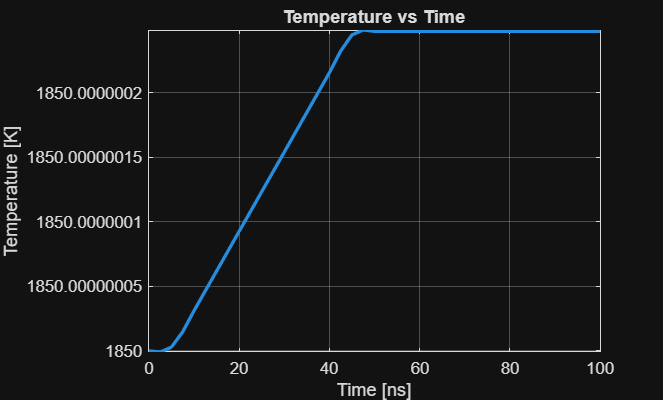

T0 = params.Tg;
rho_s = params.rho_s(T0);
rho_a = params.rho_a(T0);
c_s = params.c_s;
c_a = params.c_a;

tspan = [0 100e-9];
dTpdt = @(t,Tp) (Qdot_abs(t) - Qdot_rad(Tp)) ./ (Ntot .* Np .* (pi/6) .* Dp.^3 .* (rho_s .* c_s .* (1 - Xa) + rho_a .* c_a .* Xa));
[t,Tp] = ode45(dTpdt,tspan,T0);

figure
plot(t*1e9, Tp, 'LineWidth', 2)
xlabel('Time [ns]')
ylabel('Temperature [K]')
title('Temperature vs Time')
grid on

LII Signal, we use top hat laser profile assumption, so no variation in radial direction.

lambda_det = linspace(600e-9,620e-9,1000); % Lemaire 2026
Rdet = 1; % flat detection assumption
S_LII = zeros(size(Tp));
for i = 1:length(Tp)

    integrand = ((Cabs_multi_s + Cabs_multi_a) ./(lambda_det.^5)) .*((Rdet ./(exp((h*c) ./ (lambda_det .* params.kB .* Tp(i))) - 1))- (Rdet ./ (exp((h*c) ./ (lambda_det .* params.kB .* params.Tg)) - 1)));
    disp(integrand);
    S_LII(i) = 8 .* pi .* h .* c.^2 .*trapz(lambda_det, integrand);
    disp(S_LII(i))

end

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

     0



   1.0e+05 *

   -4.3741   -4.3754   -4.3778   -4.3778   -4.3790   -4.3787   -4.3798   -4.3823   -4.3835   -4.3848   -4.3831   -4.3832   -4.3871   -4.3880   -4.3880   -4.3891   -4.3902   -4.3926   -4.3926   -4.3950   -4.3935   -4.3946   -4.3973   -4.3968   -4.3996   -4.4009   -4.4005   -4.4030   -4.4042   -4.4041   -4.4039   -4.4050   -4.4089   -4.4088   -4.4098   -4.4109   -4.4095   -4.4121   -4.4132   -4.4143   -4.4143   -4.4153   -4.4180   -4.4190   -4.4189   -4.4187   -4.4200   -4.4238   -4.4222   -4.4248   -4.4259   -4.4273   -4.4295   -4.4308   -4.4306   -4.4303   -4.4303   -4.4341   -4.4339   -4.4352   -4.4349   -4.4361   -4.4372   -4.4385   -4.4397   -4.4396   -4.4406   -4.4432   -4.4444   -4.4455   -4.4468   -4.4451   -4.4478   -4.4488   -4.4501   -4.4513   -4.4509   -4.4523   -4.4548   -4.4559   -4.4571   -4.4569   -4.4567   -4.4593   -4.4605   -4.4615   -4.4615   -4.4641   -4.4637   -4.4652   -4.4663   -4.4673   -4.4686   -4.4696   -4.4710   -4.4722   -4.4733   -4.4717   -4.

  -1.4682e-17



   1.0e+06 *

    1.4464    1.4468    1.4470    1.4473    1.4477    1.4481    1.4483    1.4487    1.4489    1.4493    1.4497    1.4502    1.4502    1.4507    1.4510    1.4515    1.4517    1.4520    1.4524    1.4528    1.4530    1.4533    1.4537    1.4539    1.4544    1.4547    1.4552    1.4553    1.4557    1.4560    1.4565    1.4568    1.4570    1.4574    1.4577    1.4580    1.4586    1.4587    1.4589    1.4595    1.4598    1.4602    1.4603    1.4607    1.4611    1.4615    1.4618    1.4620    1.4625    1.4629    1.4632    1.4634    1.4637    1.4639    1.4644    1.4647    1.4652    1.4653    1.4659    1.4661    1.4666    1.4669    1.4673    1.4674    1.4679    1.4683    1.4686    1.4688    1.4692    1.4696    1.4698    1.4704    1.4705    1.4709    1.4713    1.4716    1.4719    1.4726    1.4725    1.4731    1.4732    1.4737    1.4741    1.4744    1.4746    1.4749    1.4754    1.4755    1.4761    1.4763    1.4767    1.4771    1.4775    1.4777    1.4781    1.4784    1.4789    1.4791    1.

   4.8545e-17



   1.0e+06 *

    7.5594    7.5613    7.5629    7.5647    7.5664    7.5683    7.5702    7.5717    7.5736    7.5752    7.5772    7.5791    7.5804    7.5823    7.5840    7.5859    7.5877    7.5893    7.5912    7.5929    7.5947    7.5966    7.5980    7.5999    7.6018    7.6034    7.6053    7.6069    7.6087    7.6106    7.6122    7.6141    7.6156    7.6174    7.6193    7.6210    7.6229    7.6246    7.6262    7.6281    7.6299    7.6317    7.6334    7.6351    7.6370    7.6386    7.6405    7.6422    7.6440    7.6458    7.6474    7.6493    7.6511    7.6527    7.6546    7.6565    7.6581    7.6598    7.6616    7.6634    7.6654    7.6670    7.6688    7.6704    7.6723    7.6742    7.6758    7.6776    7.6793    7.6812    7.6830    7.6848    7.6864    7.6880    7.6901    7.6918    7.6936    7.6955    7.6971    7.6989    7.7006    7.7024    7.7043    7.7060    7.7077    7.7096    7.7113    7.7130    7.7149    7.7165    7.7184    7.7203    7.7219    7.7239    7.7253    7.7272    7.7293    7.7309    7.

   2.5373e-16



   1.0e+07 *

    1.5953    1.5957    1.5960    1.5964    1.5968    1.5971    1.5975    1.5979    1.5982    1.5986    1.5990    1.5994    1.5997    1.6001    1.6005    1.6008    1.6012    1.6016    1.6019    1.6023    1.6027    1.6031    1.6034    1.6038    1.6042    1.6046    1.6049    1.6053    1.6057    1.6060    1.6064    1.6068    1.6071    1.6075    1.6079    1.6083    1.6087    1.6090    1.6094    1.6097    1.6101    1.6105    1.6109    1.6112    1.6116    1.6120    1.6124    1.6127    1.6131    1.6135    1.6139    1.6142    1.6146    1.6150    1.6153    1.6157    1.6161    1.6164    1.6168    1.6172    1.6176    1.6180    1.6183    1.6187    1.6191    1.6195    1.6198    1.6202    1.6206    1.6210    1.6213    1.6217    1.6221    1.6224    1.6228    1.6232    1.6236    1.6240    1.6243    1.6247    1.6250    1.6255    1.6258    1.6262    1.6265    1.6269    1.6273    1.6277    1.6281    1.6284    1.6288    1.6292    1.6296    1.6299    1.6303    1.6307    1.6311    1.6315    1.

   5.3544e-16



   1.0e+07 *

    2.3872    2.3877    2.3883    2.3888    2.3894    2.3899    2.3905    2.3911    2.3916    2.3922    2.3927    2.3933    2.3938    2.3944    2.3949    2.3955    2.3961    2.3966    2.3972    2.3977    2.3983    2.3988    2.3994    2.3999    2.4005    2.4010    2.4016    2.4022    2.4027    2.4033    2.4038    2.4044    2.4049    2.4055    2.4061    2.4066    2.4072    2.4077    2.4083    2.4088    2.4094    2.4100    2.4105    2.4111    2.4116    2.4122    2.4128    2.4133    2.4139    2.4144    2.4150    2.4155    2.4161    2.4166    2.4172    2.4178    2.4183    2.4189    2.4194    2.4200    2.4206    2.4211    2.4217    2.4222    2.4228    2.4234    2.4239    2.4245    2.4250    2.4256    2.4261    2.4267    2.4273    2.4278    2.4284    2.4290    2.4295    2.4301    2.4306    2.4312    2.4318    2.4323    2.4329    2.4334    2.4340    2.4345    2.4351    2.4357    2.4362    2.4368    2.4374    2.4379    2.4385    2.4391    2.4396    2.4402    2.4407    2.4413    2.

   8.0124e-16



   1.0e+07 *

    3.1791    3.1798    3.1805    3.1813    3.1820    3.1827    3.1835    3.1842    3.1850    3.1857    3.1864    3.1872    3.1879    3.1886    3.1894    3.1901    3.1909    3.1916    3.1923    3.1931    3.1938    3.1946    3.1953    3.1961    3.1968    3.1975    3.1983    3.1990    3.1998    3.2005    3.2013    3.2020    3.2027    3.2035    3.2042    3.2049    3.2057    3.2064    3.2072    3.2079    3.2087    3.2094    3.2101    3.2109    3.2116    3.2124    3.2131    3.2138    3.2146    3.2153    3.2161    3.2168    3.2176    3.2183    3.2190    3.2198    3.2205    3.2213    3.2220    3.2228    3.2235    3.2243    3.2250    3.2257    3.2265    3.2273    3.2280    3.2287    3.2295    3.2302    3.2310    3.2317    3.2325    3.2332    3.2340    3.2347    3.2354    3.2362    3.2369    3.2377    3.2384    3.2392    3.2399    3.2407    3.2414    3.2422    3.2429    3.2436    3.2444    3.2451    3.2459    3.2466    3.2474    3.2481    3.2489    3.2496    3.2504    3.2511    3.

   1.0670e-15



   1.0e+07 *

    3.9710    3.9719    3.9728    3.9737    3.9746    3.9756    3.9765    3.9774    3.9783    3.9792    3.9802    3.9811    3.9820    3.9829    3.9839    3.9848    3.9857    3.9866    3.9876    3.9885    3.9894    3.9904    3.9913    3.9922    3.9931    3.9940    3.9950    3.9959    3.9968    3.9977    3.9987    3.9996    4.0005    4.0014    4.0024    4.0033    4.0042    4.0051    4.0061    4.0070    4.0079    4.0089    4.0098    4.0107    4.0116    4.0126    4.0135    4.0144    4.0153    4.0163    4.0172    4.0181    4.0190    4.0200    4.0209    4.0218    4.0228    4.0237    4.0246    4.0256    4.0265    4.0274    4.0284    4.0293    4.0302    4.0312    4.0321    4.0330    4.0339    4.0349    4.0358    4.0367    4.0376    4.0386    4.0395    4.0404    4.0414    4.0423    4.0432    4.0442    4.0451    4.0460    4.0470    4.0479    4.0488    4.0498    4.0507    4.0516    4.0526    4.0535    4.0544    4.0554    4.0563    4.0572    4.0582    4.0591    4.0600    4.0610    4.

   1.3328e-15



   1.0e+07 *

    4.7628    4.7639    4.7650    4.7661    4.7673    4.7684    4.7695    4.7706    4.7717    4.7728    4.7739    4.7750    4.7761    4.7772    4.7783    4.7794    4.7806    4.7817    4.7828    4.7839    4.7850    4.7861    4.7872    4.7883    4.7894    4.7905    4.7917    4.7927    4.7939    4.7950    4.7961    4.7972    4.7983    4.7994    4.8005    4.8016    4.8027    4.8038    4.8050    4.8061    4.8072    4.8083    4.8094    4.8105    4.8117    4.8128    4.8139    4.8150    4.8161    4.8172    4.8183    4.8194    4.8205    4.8216    4.8228    4.8239    4.8250    4.8261    4.8272    4.8283    4.8295    4.8306    4.8317    4.8328    4.8339    4.8350    4.8362    4.8373    4.8384    4.8395    4.8406    4.8417    4.8428    4.8439    4.8451    4.8462    4.8473    4.8484    4.8496    4.8507    4.8518    4.8529    4.8540    4.8551    4.8563    4.8574    4.8585    4.8596    4.8607    4.8619    4.8630    4.8641    4.8652    4.8663    4.8675    4.8686    4.8697    4.8708    4.

   1.5986e-15



   1.0e+07 *

    5.5547    5.5560    5.5573    5.5586    5.5599    5.5612    5.5625    5.5638    5.5650    5.5663    5.5676    5.5689    5.5702    5.5715    5.5728    5.5741    5.5754    5.5767    5.5780    5.5793    5.5806    5.5818    5.5831    5.5845    5.5857    5.5870    5.5883    5.5896    5.5909    5.5922    5.5935    5.5948    5.5961    5.5974    5.5987    5.6000    5.6013    5.6026    5.6039    5.6052    5.6065    5.6078    5.6091    5.6103    5.6117    5.6129    5.6142    5.6155    5.6168    5.6181    5.6194    5.6207    5.6220    5.6233    5.6246    5.6259    5.6272    5.6285    5.6298    5.6311    5.6324    5.6338    5.6350    5.6363    5.6376    5.6389    5.6402    5.6415    5.6428    5.6441    5.6454    5.6468    5.6480    5.6493    5.6507    5.6520    5.6533    5.6546    5.6559    5.6572    5.6585    5.6598    5.6611    5.6624    5.6637    5.6650    5.6663    5.6676    5.6689    5.6702    5.6715    5.6728    5.6741    5.6754    5.6767    5.6780    5.6794    5.6807    5.

   1.8644e-15



   1.0e+07 *

    6.3466    6.3481    6.3496    6.3510    6.3525    6.3540    6.3555    6.3569    6.3584    6.3599    6.3614    6.3628    6.3643    6.3658    6.3673    6.3688    6.3702    6.3717    6.3732    6.3747    6.3761    6.3776    6.3791    6.3806    6.3820    6.3835    6.3850    6.3865    6.3879    6.3894    6.3909    6.3924    6.3939    6.3954    6.3968    6.3983    6.3998    6.4013    6.4028    6.4042    6.4057    6.4072    6.4087    6.4102    6.4116    6.4131    6.4146    6.4161    6.4176    6.4191    6.4206    6.4220    6.4235    6.4250    6.4265    6.4280    6.4295    6.4309    6.4324    6.4339    6.4354    6.4369    6.4384    6.4398    6.4413    6.4428    6.4443    6.4458    6.4473    6.4488    6.4503    6.4518    6.4532    6.4547    6.4562    6.4577    6.4592    6.4607    6.4622    6.4637    6.4651    6.4666    6.4682    6.4696    6.4711    6.4726    6.4741    6.4756    6.4771    6.4786    6.4801    6.4815    6.4830    6.4845    6.4860    6.4875    6.4890    6.4905    6.

   2.1302e-15



   1.0e+07 *

    7.1385    7.1402    7.1418    7.1435    7.1451    7.1468    7.1485    7.1501    7.1518    7.1534    7.1551    7.1568    7.1584    7.1601    7.1617    7.1634    7.1651    7.1667    7.1684    7.1700    7.1717    7.1734    7.1750    7.1767    7.1784    7.1800    7.1817    7.1833    7.1850    7.1867    7.1883    7.1900    7.1917    7.1933    7.1950    7.1967    7.1983    7.2000    7.2017    7.2033    7.2050    7.2067    7.2083    7.2100    7.2117    7.2133    7.2150    7.2166    7.2183    7.2200    7.2217    7.2233    7.2250    7.2267    7.2283    7.2300    7.2317    7.2333    7.2350    7.2367    7.2384    7.2401    7.2417    7.2434    7.2450    7.2467    7.2484    7.2501    7.2517    7.2534    7.2551    7.2568    7.2584    7.2601    7.2618    7.2635    7.2652    7.2668    7.2685    7.2702    7.2718    7.2735    7.2752    7.2769    7.2785    7.2802    7.2819    7.2836    7.2852    7.2869    7.2886    7.2903    7.2920    7.2936    7.2953    7.2970    7.2987    7.3004    7.

   2.3960e-15



   1.0e+07 *

    7.9304    7.9322    7.9341    7.9359    7.9378    7.9396    7.9414    7.9433    7.9451    7.9470    7.9488    7.9507    7.9525    7.9543    7.9562    7.9580    7.9599    7.9617    7.9636    7.9654    7.9673    7.9691    7.9710    7.9728    7.9747    7.9765    7.9784    7.9802    7.9821    7.9839    7.9858    7.9876    7.9894    7.9913    7.9931    7.9950    7.9969    7.9987    8.0005    8.0024    8.0043    8.0061    8.0079    8.0098    8.0117    8.0135    8.0154    8.0172    8.0191    8.0209    8.0228    8.0246    8.0265    8.0283    8.0302    8.0321    8.0339    8.0357    8.0376    8.0395    8.0413    8.0432    8.0450    8.0469    8.0488    8.0506    8.0525    8.0543    8.0562    8.0581    8.0599    8.0618    8.0636    8.0655    8.0674    8.0692    8.0711    8.0729    8.0748    8.0767    8.0785    8.0804    8.0822    8.0841    8.0860    8.0878    8.0897    8.0915    8.0934    8.0953    8.0971    8.0990    8.1009    8.1027    8.1046    8.1065    8.1083    8.1102    8.

   2.6618e-15



   1.0e+08 *

    0.8722    0.8724    0.8726    0.8728    0.8730    0.8732    0.8734    0.8736    0.8738    0.8741    0.8743    0.8745    0.8747    0.8749    0.8751    0.8753    0.8755    0.8757    0.8759    0.8761    0.8763    0.8765    0.8767    0.8769    0.8771    0.8773    0.8775    0.8777    0.8779    0.8781    0.8783    0.8785    0.8787    0.8789    0.8791    0.8793    0.8795    0.8797    0.8799    0.8801    0.8804    0.8806    0.8808    0.8810    0.8812    0.8814    0.8816    0.8818    0.8820    0.8822    0.8824    0.8826    0.8828    0.8830    0.8832    0.8834    0.8836    0.8838    0.8840    0.8842    0.8844    0.8846    0.8848    0.8850    0.8852    0.8855    0.8857    0.8859    0.8861    0.8863    0.8865    0.8867    0.8869    0.8871    0.8873    0.8875    0.8877    0.8879    0.8881    0.8883    0.8885    0.8887    0.8889    0.8891    0.8893    0.8895    0.8897    0.8900    0.8902    0.8904    0.8906    0.8908    0.8910    0.8912    0.8914    0.8916    0.8918    0.8920    0.

   2.9276e-15



   1.0e+08 *

    0.9514    0.9516    0.9519    0.9521    0.9523    0.9525    0.9527    0.9530    0.9532    0.9534    0.9536    0.9539    0.9541    0.9543    0.9545    0.9547    0.9550    0.9552    0.9554    0.9556    0.9558    0.9561    0.9563    0.9565    0.9567    0.9569    0.9572    0.9574    0.9576    0.9578    0.9581    0.9583    0.9585    0.9587    0.9589    0.9592    0.9594    0.9596    0.9598    0.9601    0.9603    0.9605    0.9607    0.9609    0.9612    0.9614    0.9616    0.9618    0.9621    0.9623    0.9625    0.9627    0.9629    0.9632    0.9634    0.9636    0.9638    0.9641    0.9643    0.9645    0.9647    0.9650    0.9652    0.9654    0.9656    0.9658    0.9661    0.9663    0.9665    0.9667    0.9670    0.9672    0.9674    0.9676    0.9678    0.9681    0.9683    0.9685    0.9687    0.9690    0.9692    0.9694    0.9696    0.9699    0.9701    0.9703    0.9705    0.9708    0.9710    0.9712    0.9714    0.9716    0.9719    0.9721    0.9723    0.9725    0.9728    0.9730    0.

   3.1934e-15



   1.0e+08 *

    1.0306    1.0308    1.0311    1.0313    1.0316    1.0318    1.0320    1.0323    1.0325    1.0328    1.0330    1.0332    1.0335    1.0337    1.0340    1.0342    1.0344    1.0347    1.0349    1.0352    1.0354    1.0356    1.0359    1.0361    1.0364    1.0366    1.0368    1.0371    1.0373    1.0376    1.0378    1.0380    1.0383    1.0385    1.0388    1.0390    1.0392    1.0395    1.0397    1.0400    1.0402    1.0404    1.0407    1.0409    1.0412    1.0414    1.0417    1.0419    1.0421    1.0424    1.0426    1.0429    1.0431    1.0433    1.0436    1.0438    1.0441    1.0443    1.0445    1.0448    1.0450    1.0453    1.0455    1.0457    1.0460    1.0462    1.0465    1.0467    1.0470    1.0472    1.0474    1.0477    1.0479    1.0482    1.0484    1.0486    1.0489    1.0491    1.0494    1.0496    1.0499    1.0501    1.0503    1.0506    1.0508    1.0511    1.0513    1.0516    1.0518    1.0520    1.0523    1.0525    1.0528    1.0530    1.0532    1.0535    1.0537    1.0540    1.

   3.4592e-15



   1.0e+08 *

    1.1098    1.1101    1.1103    1.1106    1.1108    1.1111    1.1113    1.1116    1.1119    1.1121    1.1124    1.1126    1.1129    1.1131    1.1134    1.1137    1.1139    1.1142    1.1144    1.1147    1.1150    1.1152    1.1155    1.1157    1.1160    1.1162    1.1165    1.1168    1.1170    1.1173    1.1175    1.1178    1.1181    1.1183    1.1186    1.1188    1.1191    1.1194    1.1196    1.1199    1.1201    1.1204    1.1206    1.1209    1.1212    1.1214    1.1217    1.1219    1.1222    1.1225    1.1227    1.1230    1.1232    1.1235    1.1238    1.1240    1.1243    1.1245    1.1248    1.1251    1.1253    1.1256    1.1258    1.1261    1.1264    1.1266    1.1269    1.1271    1.1274    1.1277    1.1279    1.1282    1.1284    1.1287    1.1290    1.1292    1.1295    1.1297    1.1300    1.1303    1.1305    1.1308    1.1310    1.1313    1.1316    1.1318    1.1321    1.1323    1.1326    1.1329    1.1331    1.1334    1.1337    1.1339    1.1342    1.1344    1.1347    1.1350    1.

   3.7250e-15



   1.0e+08 *

    1.1965    1.1968    1.1971    1.1974    1.1977    1.1979    1.1982    1.1985    1.1988    1.1990    1.1993    1.1996    1.1999    1.2002    1.2004    1.2007    1.2010    1.2013    1.2016    1.2018    1.2021    1.2024    1.2027    1.2029    1.2032    1.2035    1.2038    1.2041    1.2043    1.2046    1.2049    1.2052    1.2055    1.2057    1.2060    1.2063    1.2066    1.2069    1.2071    1.2074    1.2077    1.2080    1.2082    1.2085    1.2088    1.2091    1.2094    1.2096    1.2099    1.2102    1.2105    1.2108    1.2110    1.2113    1.2116    1.2119    1.2122    1.2124    1.2127    1.2130    1.2133    1.2136    1.2138    1.2141    1.2144    1.2147    1.2150    1.2152    1.2155    1.2158    1.2161    1.2164    1.2166    1.2169    1.2172    1.2175    1.2178    1.2181    1.2183    1.2186    1.2189    1.2192    1.2195    1.2197    1.2200    1.2203    1.2206    1.2209    1.2211    1.2214    1.2217    1.2220    1.2223    1.2225    1.2228    1.2231    1.2234    1.2237    1.

   4.0161e-15



   1.0e+08 *

    1.2613    1.2616    1.2619    1.2622    1.2625    1.2628    1.2631    1.2634    1.2636    1.2639    1.2642    1.2645    1.2648    1.2651    1.2654    1.2657    1.2660    1.2663    1.2666    1.2669    1.2672    1.2675    1.2678    1.2680    1.2683    1.2686    1.2689    1.2692    1.2695    1.2698    1.2701    1.2704    1.2707    1.2710    1.2713    1.2716    1.2719    1.2722    1.2725    1.2728    1.2731    1.2733    1.2736    1.2739    1.2742    1.2745    1.2748    1.2751    1.2754    1.2757    1.2760    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2786    1.2789    1.2792    1.2795    1.2798    1.2801    1.2804    1.2807    1.2810    1.2813    1.2816    1.2819    1.2822    1.2825    1.2828    1.2831    1.2834    1.2837    1.2840    1.2843    1.2846    1.2849    1.2852    1.2855    1.2857    1.2860    1.2863    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.

   4.2335e-15



   1.0e+08 *

    1.2809    1.2812    1.2815    1.2818    1.2821    1.2824    1.2827    1.2830    1.2833    1.2836    1.2839    1.2842    1.2845    1.2848    1.2851    1.2854    1.2857    1.2860    1.2863    1.2866    1.2869    1.2872    1.2875    1.2878    1.2881    1.2884    1.2887    1.2890    1.2893    1.2896    1.2899    1.2902    1.2905    1.2908    1.2911    1.2914    1.2917    1.2920    1.2923    1.2926    1.2929    1.2932    1.2935    1.2938    1.2941    1.2944    1.2947    1.2950    1.2953    1.2956    1.2959    1.2962    1.2965    1.2968    1.2971    1.2974    1.2977    1.2980    1.2983    1.2986    1.2989    1.2992    1.2995    1.2998    1.3001    1.3004    1.3007    1.3010    1.3013    1.3016    1.3019    1.3022    1.3025    1.3028    1.3031    1.3034    1.3037    1.3040    1.3043    1.3046    1.3049    1.3052    1.3055    1.3058    1.3061    1.3064    1.3067    1.3070    1.3073    1.3076    1.3079    1.3082    1.3085    1.3088    1.3091    1.3094    1.3097    1.3100    1.

   4.2994e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



   1.0e+08 *

    1.2758    1.2761    1.2763    1.2766    1.2769    1.2772    1.2775    1.2778    1.2781    1.2784    1.2787    1.2790    1.2793    1.2796    1.2799    1.2802    1.2805    1.2808    1.2811    1.2814    1.2817    1.2820    1.2823    1.2826    1.2829    1.2832    1.2835    1.2838    1.2841    1.2844    1.2847    1.2850    1.2853    1.2856    1.2859    1.2862    1.2864    1.2867    1.2870    1.2873    1.2876    1.2879    1.2882    1.2885    1.2888    1.2891    1.2894    1.2897    1.2900    1.2903    1.2906    1.2909    1.2912    1.2915    1.2918    1.2921    1.2924    1.2927    1.2930    1.2933    1.2936    1.2939    1.2942    1.2945    1.2948    1.2951    1.2954    1.2957    1.2960    1.2963    1.2966    1.2969    1.2972    1.2975    1.2978    1.2981    1.2984    1.2987    1.2990    1.2993    1.2996    1.2999    1.3002    1.3005    1.3008    1.3011    1.3014    1.3017    1.3020    1.3023    1.3026    1.3029    1.3032    1.3035    1.3038    1.3041    1.3044    1.3047    1.

   4.2820e-15



S_LII = S_LII ./ max(S_LII);
disp(max(S_LII));

     1



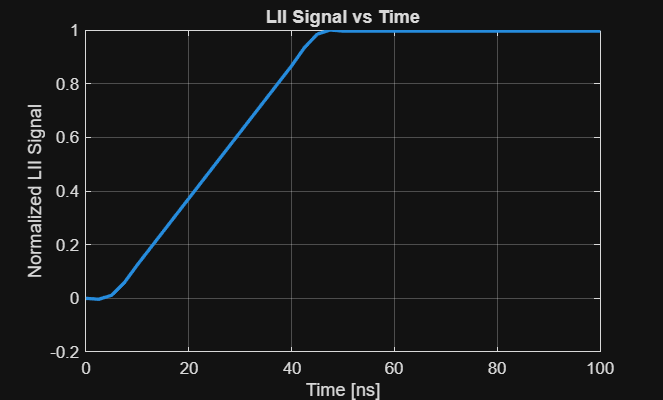

figure
plot(t*1e9,S_LII,'LineWidth',2)

xlabel('Time [ns]')
ylabel('Normalized LII Signal')
title('LII Signal vs Time')

grid on

Peak LII vs Laser Fluence

F_vec = linspace(0.01,3,40) * 1e4;
disp(F_vec);

   1.0e+04 *

    0.0100    0.0867    0.1633    0.2400    0.3167    0.3933    0.4700    0.5467    0.6233    0.7000    0.7767    0.8533    0.9300    1.0067    1.0833    1.1600    1.2367    1.3133    1.3900    1.4667    1.5433    1.6200    1.6967    1.7733    1.8500    1.9267    2.0033    2.0800    2.1567    2.2333    2.3100    2.3867    2.4633    2.5400    2.6167    2.6933    2.7700    2.8467    2.9233    3.0000



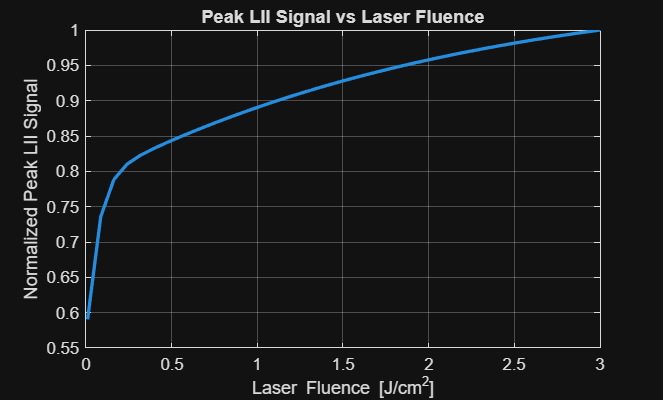

LII_peak = zeros(size(F_vec));

for j = 1:length(F_vec)
    qn_test = q_exp_norm(t_test).^n;
    norm_qn = trapz(t_test, qn_test);

    F_current = F_vec(j);

    I = @(t) F_current .* q_exp_norm(t);
    k_ls = @(t) (1 - Xa) .* (lambda_l ./ (n .* h .* c)) .* ((sigma_lambdan_s .* pi .* Dp.^3 .* Nss) ./ 6) .* (B_lambdan_s.^(-n)) .* (1 ./ norm_qn) .* (1 - exp(-((I(t) ./ B_lambdan_s).^n)));
    k_la = @(t) Xa .* (lambda_l ./ (n .* h .* c)) .* ((sigma_lambdan_a .* pi .* Dp.^3 .* Nsa) ./ 6) .* (B_lambdan_a.^(-n)) .* (1 ./ norm_qn) .* (1 - exp(-((I(t) ./ B_lambdan_a).^n)));
    Qdot_abs = @(t) Cabs_multi_s.*f1s.*B1s.*(1-exp(-(I(t))./B1s)) + Cabs_multi_a.*f1a.*B1a.*(1-exp(-(I(t))./B1a)) + Np.*n.*(h*c/lambda_l).*(k_ls(t)+k_la(t));

    dTpdt = @(t,Tp) Qdot_abs(t) ./ (Np .* (pi/6) .* Dp.^3 .* (rho_s .* c_s .* (1 - Xa) + rho_a .* c_a .* Xa));

    [t,Tp] = ode45(dTpdt,tspan,T0);

    S_temp = zeros(size(Tp));

    for i = 1:length(Tp)
        integrand = ((Cabs_multi_s + Cabs_multi_a) ./ (lambda_det.^5)) .* ((Rdet ./ (exp((h*c) ./ (lambda_det .* params.kB .* Tp(i))) - 1)) - (Rdet ./ (exp((h*c) ./ (lambda_det .* params.kB .* params.Tg)) - 1)));
        S_temp(i) = 8 .* pi .* h .* c.^2 .* trapz(lambda_det,integrand);
    end
    LII_peak(j) = max(S_temp);
end

LII_peak = LII_peak ./ max(LII_peak);

figure
plot(F_vec./1e4,LII_peak,'LineWidth',2)
xlabel('Laser Fluence [J/cm^2]')
ylabel('Normalized Peak LII Signal')
title('Peak LII Signal vs Laser Fluence')
grid on